syms x y ;
f = 3*x.^2+cos(4*x*y) - exp(2*y)

$$f = \cos\left(4\,x\,y\right)-{\mathrm{e}}^{2\,y}+3\,x^{2}$$

taylor(f,[x,y],[2,1],'Order',4)

$$ans = \cos\left(8\right)-{\mathrm{e}}^{2}+\frac{32\,\sin\left(8\right)\,{\left(x-2\right)}^{3}}{3}-\left(y-1\right)\,\left(2\,{\mathrm{e}}^{2}+8\,\sin\left(8\right)\right)-\left(4\,\sin\left(8\right)-12\right)\,\left(x-2\right)-{\left(y-1\right)}^{2}\,\left(32\,\cos\left(8\right)+2\,{\mathrm{e}}^{2}\right)-{\left(y-1\right)}^{3}\,\left(\frac{4\,{\mathrm{e}}^{2}}{3}-\frac{256\,\sin\left(8\right)}{3}\right)-\left(8\,\cos\left(8\right)-3\right)\,{\left(x-2\right)}^{2}-\left(x-2\right)\,\left(y-1\right)\,\left(32\,\cos\left(8\right)+4\,\sin\left(8\right)\right)-{\left(x-2\right)}^{2}\,\left(y-1\right)\,\left(16\,\cos\left(8\right)-64\,\sin\left(8\right)\right)-\left(x-2\right)\,{\left(y-1\right)}^{2}\,\left(32\,\cos\left(8\right)-128\,\sin\left(8\right)\right)+12$$


f1 = x.^2 + y.^2 + 1/(x.^2 + y.^2)

$$f1 = \frac{1}{x^{2}+y^{2}}+x^{2}+y^{2}$$

taylor(f1,[x,y],[3,5],'Order',4)

$$ans = \frac{3465\,x}{578}+\frac{5775\,y}{578}+\frac{15\,\left(x-3\right)\,\left(y-5\right)}{4913}+\frac{19653\,{\left(x-3\right)}^{2}}{19652}+\frac{12\,{\left(x-3\right)}^{3}}{83521}+\frac{19685\,{\left(y-5\right)}^{2}}{19652}-\frac{20\,{\left(y-5\right)}^{3}}{83521}-\frac{25\,{\left(x-3\right)}^{2}\,\left(y-5\right)}{83521}-\frac{87\,\left(x-3\right)\,{\left(y-5\right)}^{2}}{83521}-\frac{1153}{34}$$


X = [5,6];
plot(X(1),X(2),'*','MarkerSize',21);
hold on;

for i=1:10
    X = X - Jako(X);
    X
    plot(X(1),X(2),'*','MarkerSize',21);
    pause(0.5);
    hold on;
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
end

X =     5.0227    6.0227
    2.4091    3.4091


X =     4.7541    5.7541
    2.4489    3.4489


X =     4.5648    5.5648
    2.5694    3.5694


X =     4.4324    5.4324
    2.6402    3.6402


X =     4.3412    5.3412
    2.6854    3.6854


X =     4.2791    5.2791
    2.7145    3.7145


X =     4.2373    5.2373
    2.7334    3.7334


X =     4.2092    5.2092
    2.7457    3.7457


X =     4.1906    5.1906
    2.7537    3.7537


X =     4.1781    5.1781
    2.7590    3.7590


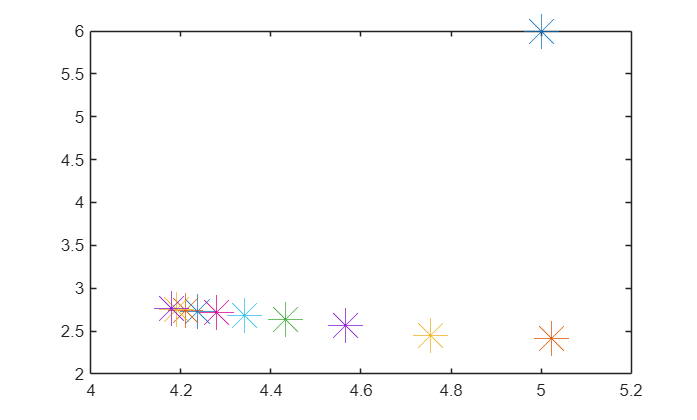

hold off;

function [xc] = Jako(X)
f1 = (X(1)-3).^2 + X(2).^2 - 9;
f2 = 3*X(2) - X(1)*2;
J = [2*(X(1) - 3) 2*X(2) ; -2*X(1) 3];
xc = pinv(J)*[f1;f2];
end


x = [-3,-1];
plot(x(1),x(2),'*','MarkerSize',21);
hold on;

for i = 1:10
    x = x - Jacko(x);
    x 
    plot(x(1),x(2),'*','MarkerSize',21);
    hold on;
    ax = gca;
    ax.XAxisLocation = 'origin'
    ax.YAxisLocation = 'origin'
end

x =    -0.5000    1.5000
   -4.0000   -2.0000


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =    -3.5962   -1.5962
    1.1154    3.1154


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =    -1.2833    0.7167
   -1.2342    0.7658


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =    -0.2812    1.7188
   -0.3084    1.6916


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =    -0.0245    1.9755
   -0.0218    1.9782


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =    -0.0002    1.9998
   -0.0002    1.9998


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =    -0.0000    2.0000
   -0.0000    2.0000


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =     0.0000    2.0000
   -0.0000    2.0000


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =     0.0000    2.0000
         0    2.0000


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x =     0.0000    2.0000
    0.0000    2.0000


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-4 0.5000]
             YLim: [-4.0000 2.0000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


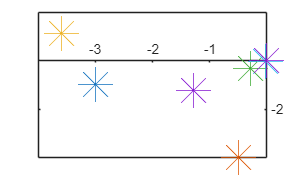


hold off;


function [xa] =  Jacko(x)
f1 = (x(1)-3).^2 + x(2).^2 - 9;
f2 = 3*x(2) - x(1).^2;
J = [2*(x(1) - 3) 2*x(2) ; -2*x(1) 3];
xa = pinv(J)*[f1;f2];
end

clc
clear
syms x y ;

x = [3;-1;0;1];

for i = 1:3
    
    Gradf = [
        2*(x(1)+10*x(2)) + 40*(x(1)-x(4))^3;
        20*(x(1)+10*x(2));
        10*(x(3)-x(4)) + 4*x(3)^3;
        -10*(x(3)-x(4)) - 40*(x(1)-x(4))^3
    ];
    
    H = [
        2 + 120*(x(1)-x(4))^2,   20,                      0,   -120*(x(1)-x(4))^2;
        20,                      200,                     0,   0;
        0,                       0,       10 + 12*x(3)^2, -10;
       -120*(x(1)-x(4))^2,       0,                     -10,   10 + 120*(x(1)-x(4))^2
    ];
    
    xc = pinv(H)*Gradf;
    x = x - xc;
    
    fprintf("Iteration %d:\n", i);
    disp(x)
    
    Lambda = eig(H)
end

Iteration 1:


    2.2481
   -0.2248
    0.9147
    0.9147



Lambda =    -0.0000
   14.8935
  200.7783
  966.3282


Iteration 2:


    1.4987
   -0.1499
    0.6098
    0.6098



Lambda =     2.1783
   22.6509
  200.2098
  433.6684


Iteration 3:


    0.9991
   -0.0999
    0.4065
    0.4065



Lambda =     1.2124
   17.7958
  184.5400
  212.5440


syms x 
syms y

f1 = (x-3).^2 + y .^2 - 9;

Iteration 1:


    2.2481
   -0.2248
    0.9147
    0.9147



Lambda =    -0.0000
   14.8935
  200.7783
  966.3282


Iteration 2:


    1.4987
   -0.1499
    0.6098
    0.6098



Lambda =     2.1783
   22.6509
  200.2098
  433.6684


Iteration 3:


    0.9991
   -0.0999
    0.4065
    0.4065



Lambda =     1.2124
   17.7958
  184.5400
  212.5440


f2 = 3*y - x.^2;
F= [f1;f2];

J = Jacobian(F,[x,y]);